## Prepare Your Data for Training

Inside the "Traffic Signs" folder, the data is already separated into Train and Test folders. 

Create an image datastore from the training dataset named `imdsSigns`:

% Select the location of the training data set:
filename = "D:\image processing coursera\DL for Computer Vision\Data\Traffic Signs\Train";

% Your code to create a datastore of training images:


Use 80% of your data for training, leaving the remaining images for validation. Make sure to randomize which images are assigned to the validation set.

imdsSigns=imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames")

imdsSigns =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Traffic Signs\Train\End Speed Limit\sign0003.png';
                              ' ...\Data\Traffic Signs\Train\End Speed Limit\sign0006.png';
                              ' ...\Data\Traffic Signs\Train\End Speed Limit\sign0011.png'
                               ... and 897 more
                              }
                     Folders: {
                              ' ...\DL for Computer Vision\Data\Traffic Signs\Train'
                              }
                      Labels: [End Speed Limit; End Speed Limit; End Speed Limit ... and 897 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @read

[imdsTrain,imdsVal]=splitEachLabel(imdsSigns,0.8,"randomized");

## Preview the Training Data

img = read(imdsSigns);
size(img)

ans =     32    32     3


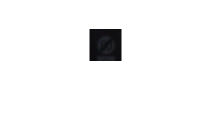

imshow(img)

All images are in RGB format, with sizes  $m \times n \times 3$, but they have a range of different sizes. Before you can train, you will have to resize these images to match the image input layer.

## Define the Network Architecture

Use the Deep Neural network with the following layers:

- `imageInputLayer`

- `convolution2dLayer`

- `reluLayer`

- `maxPooling2dLayer`

- `fullyConnectedLayer`

- `softmaxLayer`

Make sure you specify the correct `OutputSize` for `fullyConnectedLayer`.

net = dlnetwork;
tempNet = [
    imageInputLayer([24 24 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(9,"Name","fc")
    softmaxLayer("Name","softmax")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

net = initialize(net);


## Resize Your Training Data

Resize the training and validation data to match the `InputSize` that you set above:

resized_imdsTrain=augmentedImageDatastore([24,24],imdsTrain)

resized_imdsTrain =   augmentedImageDatastore with properties:

             NumObservations: 720
                       Files: {720×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [24 24]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


resized_imdsVal=augmentedImageDatastore([24,24],imdsVal)

resized_imdsVal =   augmentedImageDatastore with properties:

             NumObservations: 180
                       Files: {180×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [24 24]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## Setting the Training Options

- Set the solver to `"adam"`

- Include the validation data you set aside earlier

- Set the Shuffle option to `"every-epoch"`

- Set the Plots option to `"training-progress"`

options= trainingOptions("adam",ValidationData=resized_imdsTrain,Shuffle="every-epoch",Plots="training-progress");


## Train the Network

It's time to train your network! 

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:12        0.001                            13.621
            1        1       00:00:13        0.001          13.725                  
           50       10       00:00:47        0.001            4.73            5.5743
          100       20       00:01:02        0.001         0.71876           0.94281
          150       30       00:01:12        0.001         0.29839           0.23145
Training stopped: Max epochs completed


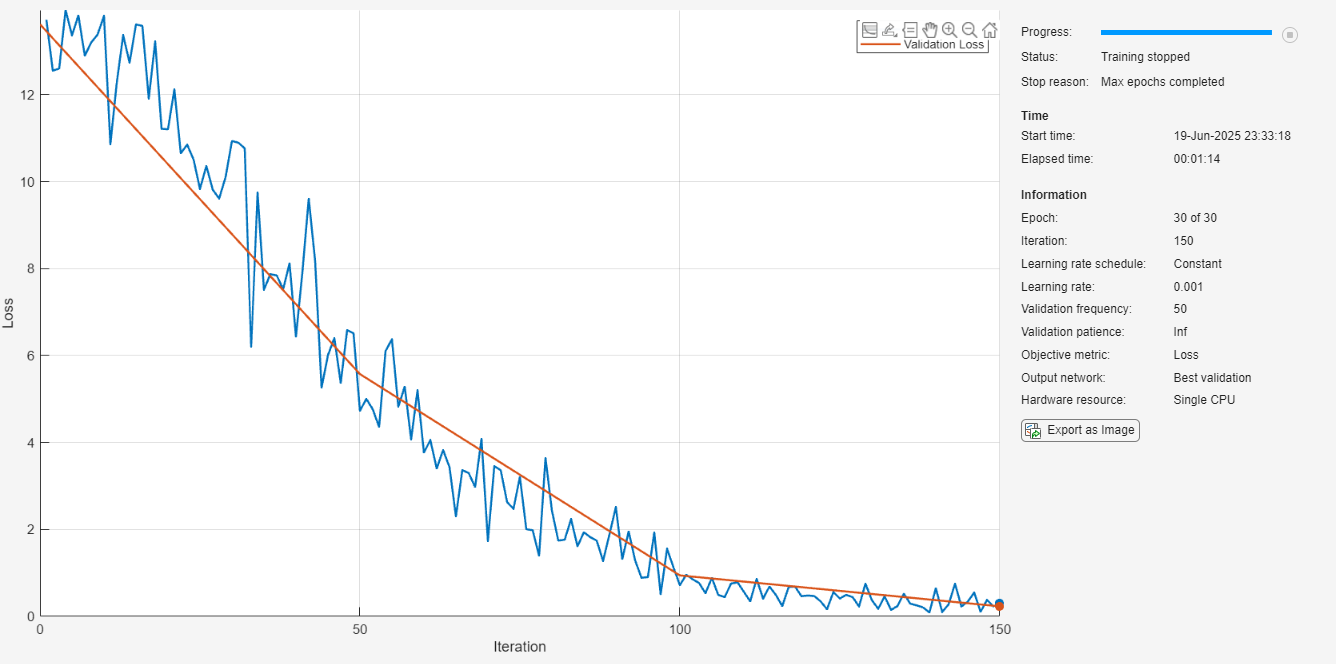

net=trainnet(resized_imdsTrain,net,"crossentropy",options);

Training took about 4 minutes on my CPU.

## Performance on Test Data

Once you have trained your network, you should examine its performance on your test data.

Don't forget to resize your images to match the expected input size for your trained network:

filenameTest = "D:\image processing coursera\DL for Computer Vision\Data\Traffic Signs\Test";
imdsTest=imageDatastore(filenameTest,"IncludeSubfolders",true,"LabelSource","foldernames");
imdsAugmentedTest=augmentedImageDatastore([24,24],imdsTest);



Finally, use your test data to evaluate your trained network, including calculating the test accuracy and creating a confusion chart. You may need to click the arrow and open your confusion charts in the figure window to see them well:

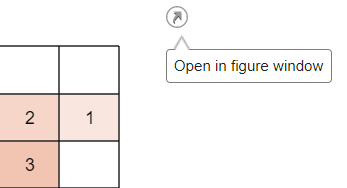

testPreds=minibatchpredict(net,imdsAugmentedTest);
testTrueClass=imdsTest

testTrueClass =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011221.png';
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011223.png';
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011224.png'
                               ... and 285 more
                              }
                     Folders: {
                              ' ...\DL for Computer Vision\Data\Traffic Signs\Test'
                              }
                      Labels: [End Speed Limit; End Speed Limit; End Speed Limit ... and 285 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     Re

classes=categories(imdsTest.Labels);
testPredsClass=scores2label(testPreds,classes);
accuracy = mean(testPredsClass == imdsTest.Labels);
disp("Test Accuracy: " + accuracy*100 + "%");

Test Accuracy: 68.4028%


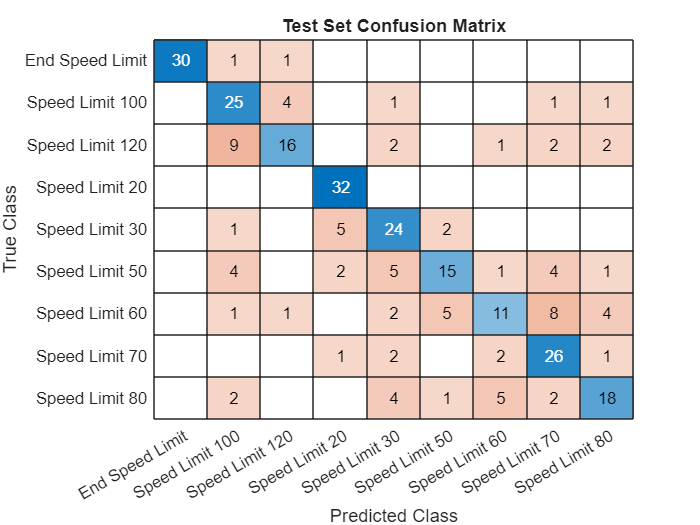


figure;
confusionchart(imdsTest.Labels, testPredsClass);
title("Test Set Confusion Matrix");